# Sample 5-6

## 周波数解析

多変量循環畳み込み

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Fourier analysis

Multivariate circular convolution

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

close all

### サンプル画像$\{u[\mathbf{n}]\}_\mathbf{n}
$の準備

(Preparation of sample image $\{u[\mathbf{n}]\}_\mathbf{n}
$)

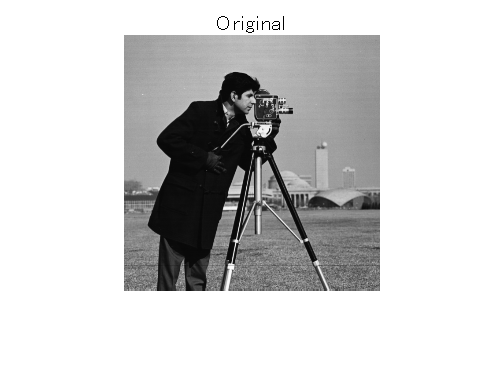

% Reading original image
u = im2double(imread('cameraman.tif'));
figure(1)
imshow(u)
title('Original')

### 線形シフト不変システムのインパルス応答 $\{h[\mathbf{n}]\}_\mathbf{n}
$ 

(Impulse response of a linear shift-invariant system $\{h[\mathbf{n}]\}_\mathbf{n}
$

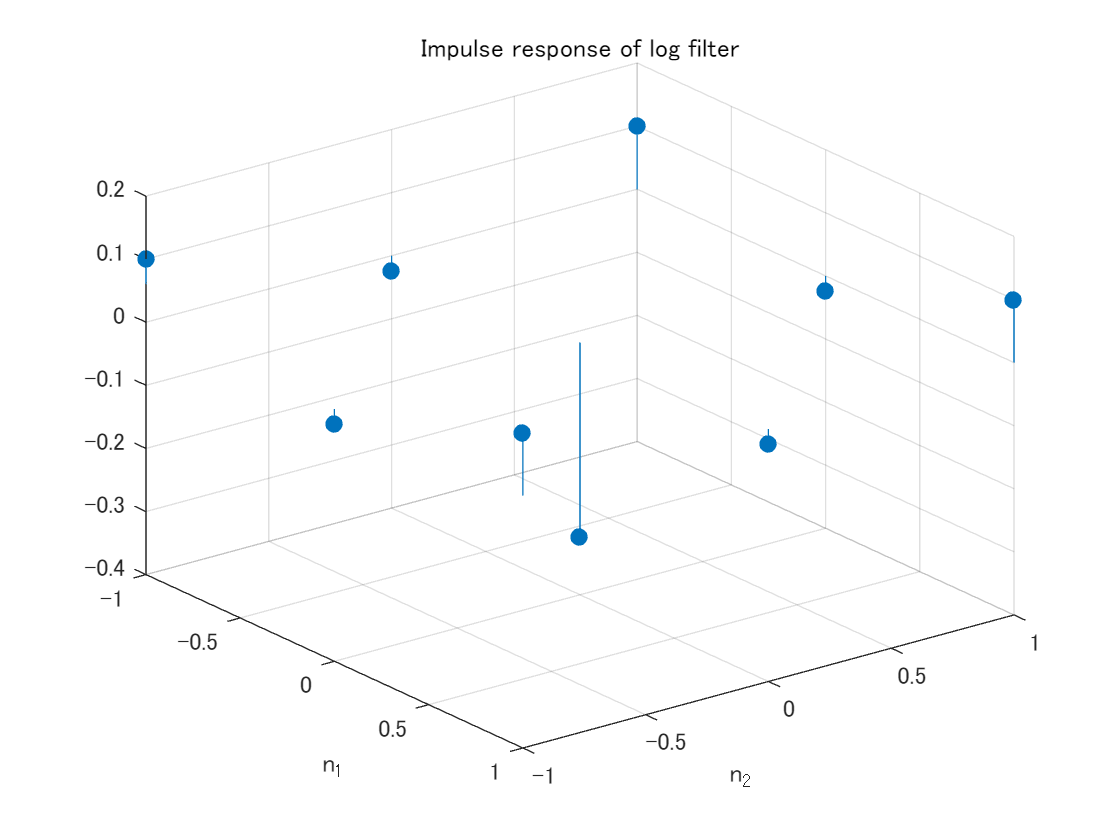

% Impulse response h[n]
hsize1 = 3;
hsize2 = 3;
sigma = 1;
ftype = "log";
h = rot90(fspecial(ftype,[hsize1 hsize2],sigma),2);
figure(2)
[n1,n2] = meshgrid(-floor((hsize2-1)/2):ceil((hsize2-1)/2),-floor((hsize1-1)/2):ceil((hsize1-1)/2));
stem3(n1,n2,h,'filled')
xlabel('n_2')
ylabel('n_1')
axis ij
title(['Impulse response of ' char(ftype) ' filter'])

### 周期行列 $\mathbf{Q}$ の循環畳み込みの出力応答$\{v[\mathbf{n}]\}_\mathbf{n}
$ 

(Output response $\{v[\mathbf{n}]\}_\mathbf{n}
$ of circular convolution with period $\mathbf{Q}$ )

循環畳み込み演算 (Circular convolution)

        
$$\{v[\mathbf{n}]\}_\mathbf{n}=\{h[\mathbf{n}]\}_\mathbf{n} \bigcirc  \{u[\mathbf{n}]\}_\mathbf{n} = \sum_{\mathbf{k}\in\Omega\subset\mathbb{Z}^2}u[\mathbf{k}]\{h[(\!(\mathbf{n}-\mathbf{k})\!)_\mathbf{Q}]\}_\mathbf{n}
$$


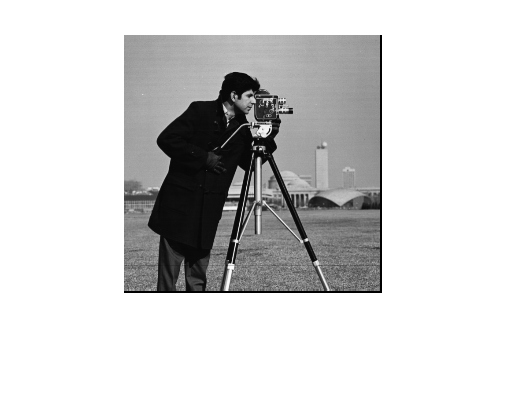

% Setting the period N
nPeriod1 =258;
nPeriod2 =258;
nPeriod = [nPeriod1 nPeriod2];
nZeroPadding = [nPeriod1 nPeriod2] - size(u);

% Zero padding
uzpd = padarray(u,nZeroPadding,0,'post');
figure(3)
imshow(uzpd)


% Output v[n]
v = imfilter(uzpd,h,'conv','circ');

### 畳み込み演算との比較

(Comparison with convolution)

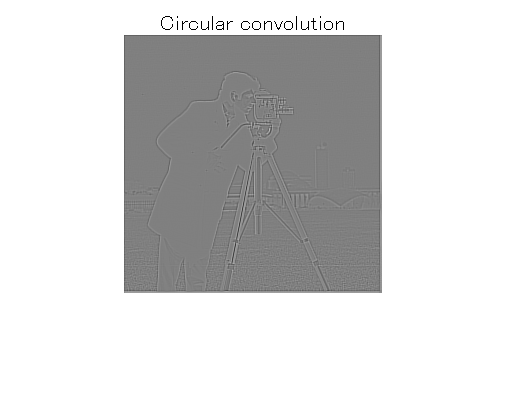

% Normal convolution
w = imfilter(u,h,'conv','full');

% v[n]
figure(4)
imshow(v+(min(v(:))<0)/2)
title('Circular convolution')

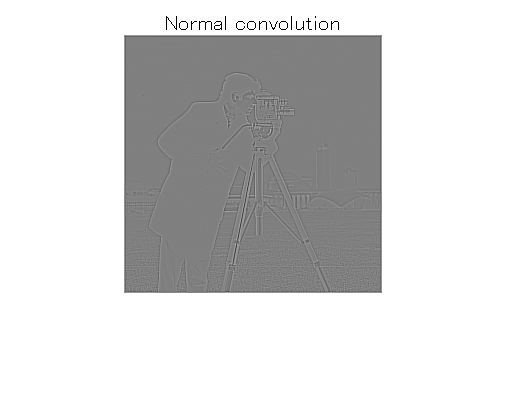

% w[n]
figure(5)
imshow(w+(min(w(:))<0)/2)
title('Normal convolution')

#### 通常の畳み込みと循環畳み込みが一致する条件

(The condition that normal convolution and circular convolution match)

        
$$\exists \mathbf{m}\in\mathbb{Z}^D\ \mathrm{s.t.}\ \{  \mathbf{n}+\mathbf{m}|\mathbf{n} \in \Omega_\mathrm{v}\}\subseteq  \mathcal{N}(\mathbf{Q})$$


        
$$\Omega_\mathrm{v}=\{\mathbf{n}+\mathbf{k}
|\mathbf{n}\in\Omega_\mathrm{u},\mathbf{k}\in\Omega_\mathrm{h}\}$$


ただし、(where)

- $\Omega_\mathrm{v}$: 出力のサポート領域 (Output support region)

- $\Omega_\mathrm{h}$: インパルス応答のサポート領域 (Support region of impulse response)

- $\Omega_\mathrm{u}$: 入力のサポート領域 (Input support region)

以下では周期行列 $\mathbf{Q}$ を対角行列 (In the following, the periodic matrix  $\mathbf{Q}$ is set to a diagonal matrix)

         
$$\mathbf{Q}=\left(\begin{array}{cc}
N_1 & 0 \\
0 & N_2 \end{array}\right)$$
 

に設定する．すなわち，(That is,)

        
$$\mathcal{N}(\mathbf{Q})=\mathcal{N}(\mathbf{Q}^T)=\{0,1,2,\cdots,N_1-1\}\times\{0,1,2,\cdots,N_2-1\}$$


        
$$N=\left|\mathcal{N}(\mathbf{Q})\right|=\left|\det(\mathbf{Q})\right|=N_1N_2$$


ただし，$\Omega_\mathrm{u}\subseteq\mathcal{N}(\mathbf{Q})$ を仮定する．( and $\Omega_\mathrm{u}\subseteq\mathcal{N}(\mathbf{Q})$ is assumed.)

【Example】もし，(If)

        
$$\Omega_\mathrm{u}=\{0,1,2,\cdots,L_{\mathrm{u}1}-1\}\times\{0,1,2,\cdots,L_{\mathrm{u}2}-1\}$$


        
$$\Omega_\mathrm{h}=\{-1,0,1\}\times\{-1,0,1\}$$


ならば，(then,)

        
$$\Omega_\mathrm{v}=\{-1,0,1,2,\cdots,L_{\mathrm{u}1}\}\times\{-1,0,1,2,\cdots,L_{\mathrm{u}2}\}.$$


よって，(Therefore, from)

        
$$\left\{  \mathbf{n}+(1,1)^T\vert \mathbf{n} \in\Omega_\mathrm{v}\}=\{0,1,2,\cdots,L_{\mathrm{u}1}+1\}\times\{0,1,2,\cdots,L_{\mathrm{u}2}+1\},$$


より，

        
$$N_1\geq L_{\mathrm{u}1}+2,\ N_2\geq L_{\mathrm{u}2}+2,$$


ならば，通常と畳み込みと循環畳み込みの結果が一致する．(then, the results of normal, convolution and circular convolution are consistent.)

% Adjusting the sizes for evaluation
dsz = size(v)-size(w);
if dsz(1) > 0
    vc = v;
    wc = padarray(w,[dsz(1) 0],0,'post');
else
    wc = w;
    vc = padarray(v,[-dsz(1) 0],0,'post');
end
if dsz(2) > 0
    wc = padarray(wc,[0 dsz(2)],0,'post');
else
    vc = padarray(vc,[0 -dsz(2)],0,'post');
end
% Compensate the circular shift
wc = circshift(wc,-ceil((size(h)-1)/2));

% Sizes and MSE
mymse = @(x,y) mean((double(x)-double(y)).^2,'all');
fprintf('Period:         N1  = %d, N2  = %d',nPeriod1,nPeriod2);

Period:         N1  = 258, N2  = 258

fprintf('Size of image:  Lu1 = %d, Lu2 = %d',size(u,1),size(u,2));

Size of image:  Lu1 = 256, Lu2 = 256

fprintf('Size of filter: Lh1 = %d, Lh2 = %d',size(h,1),size(h,2));

Size of filter: Lh1 = 3, Lh2 = 3

fprintf('MSE: %f', mymse(vc,wc))

MSE: 0.000000

### 入力信号 $\{u[\mathbf{n}]\}_\mathbf{n}
$ のDFT

(DFT of input signal $\{u[\mathbf{n}]\}_\mathbf{n}
$)

        
$$U[\mathbf{k}]=\sum_{\mathbf{n}\in\mathcal{N}(\mathbf{Q})} u[\mathbf{n}] e^{-\j 2\pi\mathbf{k}^T\mathbf{Q}^{-1}\mathbf{n}},\ \mathbf{k}\in\mathcal{N}(\mathbf{Q}^T)
$$


% DFT of u[n]
U = fftn(u,nPeriod);

### フィルタ $\{h[\mathbf{n}]\}_\mathbf{n}
$ のDFT

(DFT of impulse response $\{h[\mathbf{n}]\}_\mathbf{n}
$)

        
$$H[\mathbf{k}]=\sum_{\mathbf{n}\in\mathcal{N}(\mathbf{Q})} h[\mathbf{n}] e^{-\j 2\pi\mathbf{k}^T\mathbf{Q}^{-1}\mathbf{n}},\ \mathbf{k}\in\mathcal{N}(\mathbf{Q}^T)
$$


% DFT of h[n]
H = fftn(h,nPeriod);

### 出力信号 $\{v[\mathbf{n}]\}_\mathbf{n}
$ のDFT

(DFT of output signal $\{v[\mathbf{n}]\}_\mathbf{n}
$)

        
$$V[\mathbf{k}]=\sum_{\mathbf{n}\in\mathcal{N}(\mathbf{Q})} v[\mathbf{n}] e^{-\j 2\pi\mathbf{k}^T\mathbf{Q}^{-1}\mathbf{n}},\ \mathbf{k}\in\mathcal{N}(\mathbf{Q}^T)

$$


% Frequency response of v[n]
V = fftn(v,nPeriod);

### DFT積

(DFT product)

        
$$V[\mathbf{k}]=H[\mathbf{k}]U[\mathbf{k}],\ \mathbf{k}\in\mathcal{N}(\mathbf{Q})$$


循環畳み込みとの比較 (Comparison with circular convolution)

% IDFT of DFT product
y = ifftn(H.*U);
% Compensate the circular shift
y = circshift(y,-ceil((size(h)-1)/2));
% MSE with the cconv result 'v'
fprintf('MSE: %f', mymse(v,y))

MSE: 0.000000

### 循環畳み込みのスペクトルノルム

(Spectral norm of the circular convolution)

        
$$\|\mathbf{T}\|_2=\sigma_1(\mathbf{T})=\max_{\mathbf{k}\in\mathcal{N}(\mathbf{Q}^T)}\left|H[\mathbf{k}]\right|$$


ただし，(where)

- $\sigma_1(\mathbf{T})$:  $\mathbf{T}$の最大特異値．(Maximum singular value of $\mathbf{T}$)

% Definition of map T as a circular convolution with h[n]
mapT = @(x) imfilter(x,h,'conv','circ');

#### 2変量循環畳み込みの行列表現

(Matrix representation of the bivariate circular convolution)

% Redefining the period
N1 =8;
N2 =8;

% Find the matrix representation of the circular convolution
N  = N1*N2;
T = zeros(N);
for idx = 1:N
    % Generating a standard basis vector
    e = zeros(N1,N2);
    e(idx) = 1;
    % Response to the standard basis vector
    T(:,idx) = reshape(mapT(e),[N 1]); 
end
% Matrix representation of the circular convolution
T

T =    -0.3079   -0.0234         0         0         0         0         0   -0.0234   -0.0234    0.1004         0         0         0         0         0    0.1004         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0234   -0.3079   -0.0234         0         0         0         0         0    0.1004   -0.0234    0.1004         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

#### スペクトルノルム

(Spectral norm)

% Function NORM evaluates the operator norm for a matrix
opnorm = norm(T,2) 

opnorm = 0.7096

#### 最大特異値

(Maximum singular value)

sigma1 = max(svd(T))

sigma1 = 0.7096

#### 最大振幅応答

(Maximum magnitude response)

H = fftn(h,[N1 N2]);
maxmgn = max(abs(H(:)))

maxmgn = 0.7096

### 関数NORMに関する注意

(Notes on the Function NORM)

行列に関するノルムを評価する際には引数の渡し方、オプションの指定に注意すること．(When evaluating the entorywise norm of a matrix, pay attention to the way of passing the arguments and options.)

% Froubenius norm 
norm(T,'fro')

ans = 2.9649


% Entrywise 2-norm, which is identical to the Frobenius norm
norm(T(:),2)

ans = 2.9649


% Operator 1-norm
norm(T,1)

ans = 0.8033


% Entrywise 1-norm
norm(T(:),1)

ans = 51.4119

© Copyright, Shogo MURAMATSU, All rights reserved.